% Load the Fisher Iris dataset
load fisheriris.mat
X = meas(1:100,:);        % Feature matrix (150 samples x 4 features)
species_2 = species(1:100,:);
y = (strcmp(species_2,'setosa'))*1 + (strcmp(species_2,'versicolor'))*2; % Convert species to numeric labels (1, 2, 3)

% Set the range of cost values to try (logarithmic scale)
cost_values = logspace(-3, 3, 7);

% Initialize an array to store the cross-validation accuracies for each cost
cv_accuracies_rbf = zeros(size(cost_values));

% Perform k-fold cross-validation with different cost values
k_fold = 5; % Number of folds for cross-validation
cv = cvpartition(y, 'KFold', k_fold);

for i = 1:length(cost_values)
    cost = cost_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        train_idx = training(cv, fold);
        test_idx = test(cv, fold);
        
        X_train = X(train_idx, :);
        y_train = y(train_idx);
        X_test = X(test_idx, :);
        y_test = y(test_idx);
        
        % Train SVM with the radial (RBF) kernel and current cost
        svm_model_rbf = fitcsvm(X_train, y_train, 'KernelFunction', 'RBF', 'BoxConstraint', cost);
        
        % Predict on the test set
        y_pred_rbf = predict(svm_model_rbf, X_test);
        
        % Compute accuracy for the current fold
        accuracy = sum(y_pred_rbf == y_test) / length(y_test);
        accuracies(fold) = accuracy;
    end
    
    % Calculate the average accuracy across all folds for the current cost
    cv_accuracies_rbf(i) = mean(accuracies);
end

% Find the cost with the highest cross-validation accuracy
[best_accuracy_rbf, best_cost_idx_rbf] = max(cv_accuracies_rbf);
best_cost_rbf = cost_values(best_cost_idx_rbf);

% Train the final SVM with the radial (RBF) kernel using the best cost on the entire dataset
final_svm_model_rbf = fitcsvm(X, y, 'KernelFunction', 'RBF', 'BoxConstraint', best_cost_rbf);

% Display the results
disp(['Best cost for Radial (RBF) Kernel SVM: ', num2str(best_cost_rbf)]);

Best cost for Radial (RBF) Kernel SVM: 0.001


disp(['Cross-validation accuracy with best cost: ', num2str(best_accuracy_rbf)]);

Cross-validation accuracy with best cost: 1


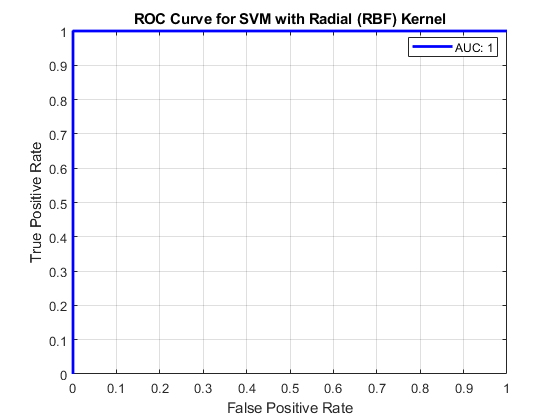


% Predict probabilities on the test set
[a, scores_rbf] = predict(final_svm_model_rbf, X_test);

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
labels_binary = y_test;
labels_binary(labels_binary ~= 1) = 0;

% Calculate the ROC curve and AUC
[X_roc_rbf, Y_roc_rbf, ~, AUC_rbf] = perfcurve(labels_binary, scores_rbf(:, 2), 0);

% Plot the ROC curve
figure;
plot(X_roc_rbf, Y_roc_rbf, 'b-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curve for SVM with Radial (RBF) Kernel');
legend(['AUC: ', num2str(AUC_rbf)], 'Location', 'Best');
grid on;ye